% scanimage computer
str_exp_date = '16-10-31';
data_dir = 'F:\Users\juyoung\data\1031';
%n_session = params.n_session;
%
matlab_dir = 'C:\Users\scanimage\Documents\MATLAB\Matlab_juyoung';
stim_dir = 'F:\Users\juyoung\mystim';
savedir = 'C:\Users\scanimage\Documents\MATLAB\Matlab_juyoung\figs_1031exp';

% My macbook pro 2012
stim_dir = ' ';
data_dir = '/Users/peterfish/Documents/1__Retina_Study/DATA_2016/16-10-31';
matlab_dir = '/Users/peterfish/Documents/Matlab-lib';

## Update and upload the library  

% Add an update, commit and push
cd(matlab_dir);             
commitStr = sprintf('Library update on %s', datestr(now));
evalc(['!git add -A; git commit -am "' commitStr '"; git push;']);

## Get PD signal for the first time

% struct g after sorting
% spikes from i-th file (experiment) and align the timestamps of 'all' cells relative to events.
% PD should provide timings of the events.
cd(data_dir);
%
[pd, ev_id, srate] = getpd('1031drift.h5');

Error using hdf5info (line 59)
Could not open file '1031drift.h5'.

Error in getpd (line 7)
fileinfo = hdf5info(filename);

save('pd.mat', 'pd');
load('16-10-31.mat');

## Get 'ex' struct

str_today = datestr(now, 'yy-mm-dd');
% up-to-date visual stimulus
cd(stim_dir);
!git pull

Permission denied (publickey). 
fatal: Could not read from remote repository.

Please make sure you have the correct access rights
and the repository exists.


% load 'ex' struct
basedir = fullfile('logs/', str_exp_date);
ex_file = fullfile(basedir,'exlog.mat');
load(ex_file);

## Load 'g' (sorted spikes) and 'pd'. Detect trigger events

cd(data_dir);
load('16-10-31.mat');
load('pd.mat');

% load ex struct
params = ex.stim{1}.params;
% Duration of repeat (one experiment)
ifi = ex.disp.ifi;
numframes = params.jumpevery;
%n_session = params.n_session;
n_session = 8;
s_duration = numframes * ifi

s_duration = 0.8823

repeat_duration = n_session * s_duration

repeat_duration = 7.0586

% event timeedges
min_interval_secs = 3*s_duration;
[ev_secs, ev_interval] = pd_event_display(pd, min_interval_secs, 0.7);

% event correction
ids_2long = find(ev_interval > 1.1*repeat_duration)

ids_2long =     46    73   117   205   272   475   795


ev_interval(ids_2long)/repeat_duration

ans =     2.0002    2.0002    2.0001    2.0002    2.0002    1.8551    1.8551


% last 2 long events are due to the function change.
missing_ids = ids_2long(1:end-2)

missing_ids =     46    73   117   205   272


missing_ev = ev_secs(missing_ids) + repeat_duration;
ev_secs_c = [ev_secs, missing_ev];
ev_secs_c = sort(ev_secs_c);

## Stimulus for RF mapping

cd(stim_dir);
% check if recreation is 'yes'
[ex, noise_stim] = rf_noise(ex, 'recreation', 'yes',  ...           
            'movieDurationSecs', (60*30), ... % 30 min
            'checkerSizeXum', 50, ...
            'checkerSizeYum', 50, ...
              'stimSizeXYum', 3500*[1 1]);

## STA analysis of sorted cells

% sorted cell list
s = list_sorted_cells(g);
% file list
s(1)

ans =              files: {'1031drift.h5'  '1031drift2.h5'  '1031rf.h5'  '1031rf2.h5'}
    N_sorted_cells: 6
               CHs: [32 38 44 51 55]
             times: {[1×98 double]  [141549 170505 170538 170616]  [30563 31503 142300 329821 713465 3935266 3941868 8973958 9058611 9262766 9342197 9377261]  [1×8864 double]}
                ch: 32


i_rf_file = 2;
%
srate = 10000;
upsampling = 2;
STA_period = 0.6;
%
j_cell = 1:5;
for j = j_cell
%    rf = STA(s(j).times{i_rf_file}/srate, STA_period, noise_stim, upsampling, 3*ex.disp.ifi);
%    title(['cell ', num2str(j)]);
end


## Exp (file) 1: Align spikes of all cells relative to trigger events (PD)

% Align spikes of a specific experiment (filename) relative to PD trigger events
i_file = 1; % file id (experiment id)
all_spikes = align_sorted_cells(s, ev_secs_c, i_file);

## Cell spikes: raster plot and rate

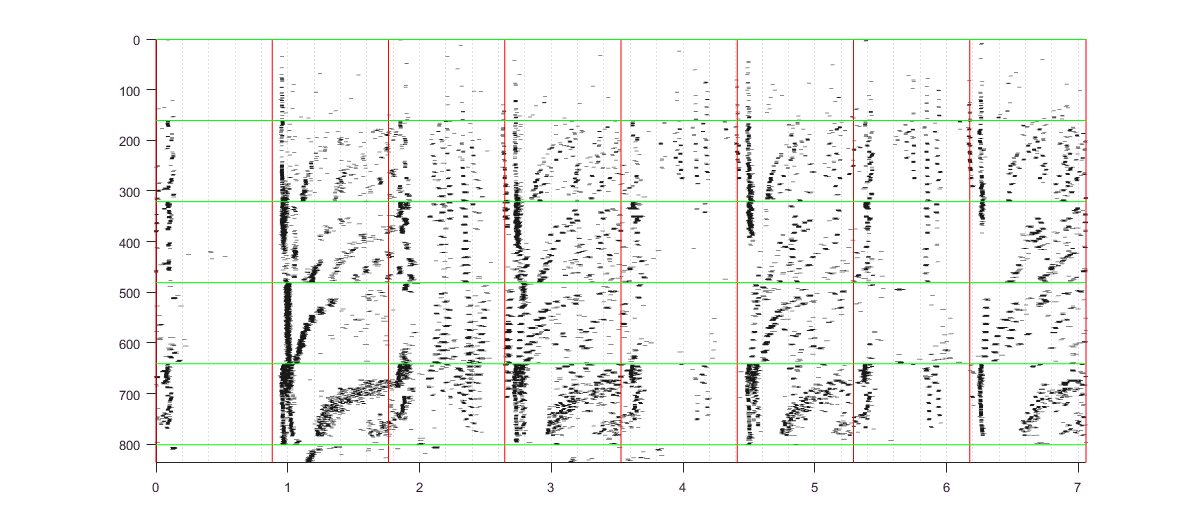

j_cell = 5; % cell id
%
n_repeat = params.n_repeat;
n_jitter = params.n_jitter;
H_lines = n_jitter*n_repeat*10; % for one speed
V_lines = (0:n_session) * s_duration;
% display
figure; set(gcf, 'Position', [20, 400, 1000, 250]); 
myraster(all_spikes{j_cell}, H_lines, V_lines); 
xlim([0, repeat_duration + 0*s_duration]);

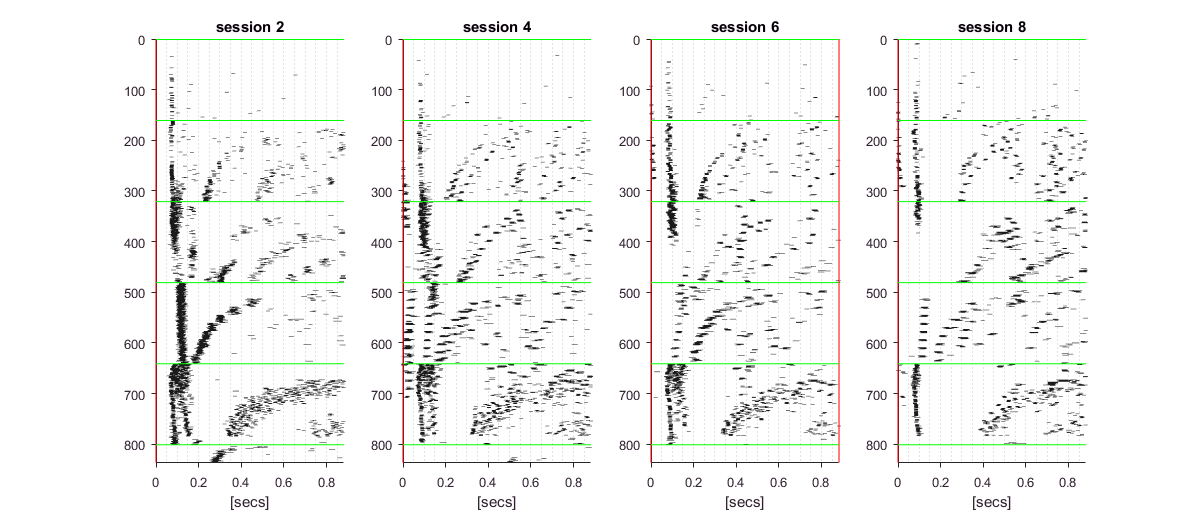

% Align (split) spikes relative to sessions
ev_session = 0:s_duration:s_duration*(n_session-1);
spikes_splited = split_to_event(all_spikes{j_cell}, ev_session);

% Focus on transitions
s_id = [2, 4, 6, 8]; % session ids of transitions
n_transitions = length(s_id);

figure; set(gcf, 'Position', [161, 212, 978, 520]);  
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    s_spikes = spikes_splited{s_id(i)}; % Use simpler name
    myraster(s_spikes, H_lines, [0, s_duration]); title(['session ',num2str(s_id(i))]); xlabel('[secs]');
end
saveas(gcf, ['cell_',num2str(j_cell)],'png');

## Plot firing rate as varying conditions

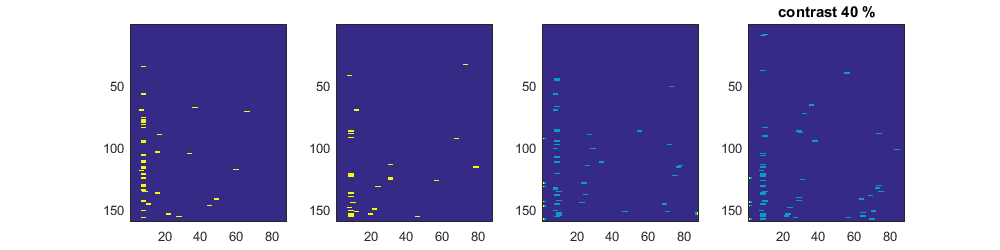

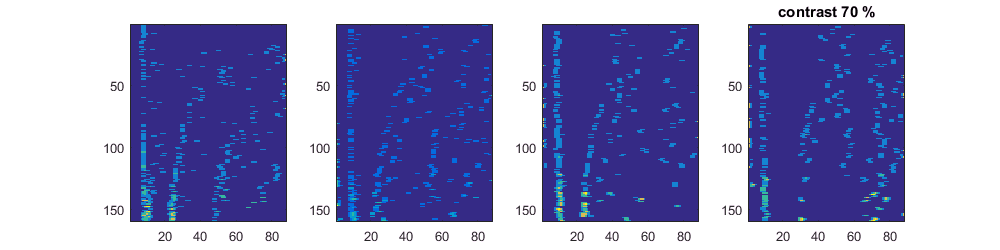

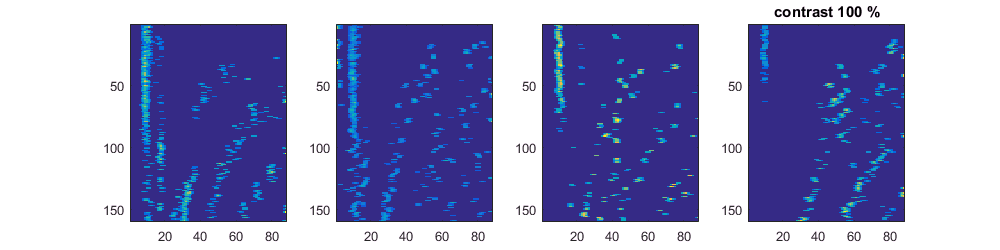

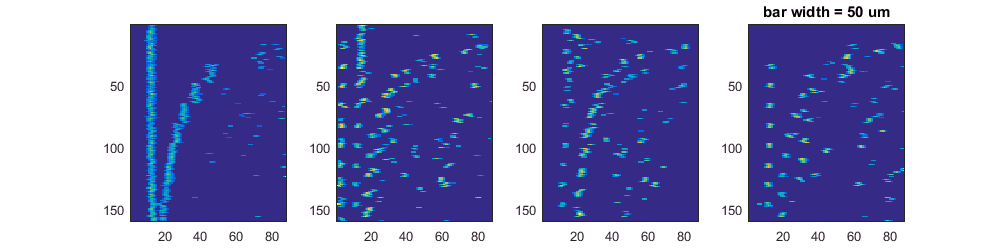

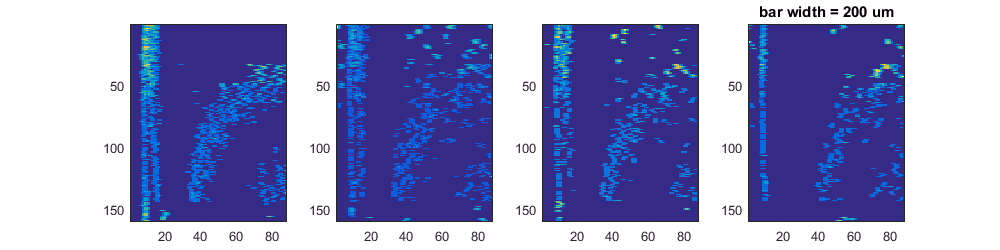

% assign line range to conditions
c_range = {1:160, 161:320, 321:480, 481:640, 641:800};
c_text = 'contrast'; c_unit = '%%'; c_values = [40, 70, 100];
%
S = sprintf([c_text, ' %d ',c_unit, '*'], c_values); D = regexp(S, '*', 'split');
c_title = D(1:(end-1));
c_title{4} = 'bar width = 50 um';
c_title{5} = 'bar width = 200 um';
% binning parameters
bin_size = 0.01;
smoothing = 3;
%
rate = cell(1, n_transitions);
for c = 1:numel(c_range)
    figure; set(gcf, 'Position', [20, 400, 1000, 250]); 
    title(c_title{c});
    for i = 1:n_transitions
        rate{i} = ts_rate_cell(spikes_splited{s_id(i)}, [0 s_duration], bin_size, smoothing); % rate is an array
        subplot(1, n_transitions, i);
        imagesc(rate{i}(c_range{c},:));
    end
    title(c_title{c});
end

## Timestamps vs Rate: Close up 'k-th' session over conditions

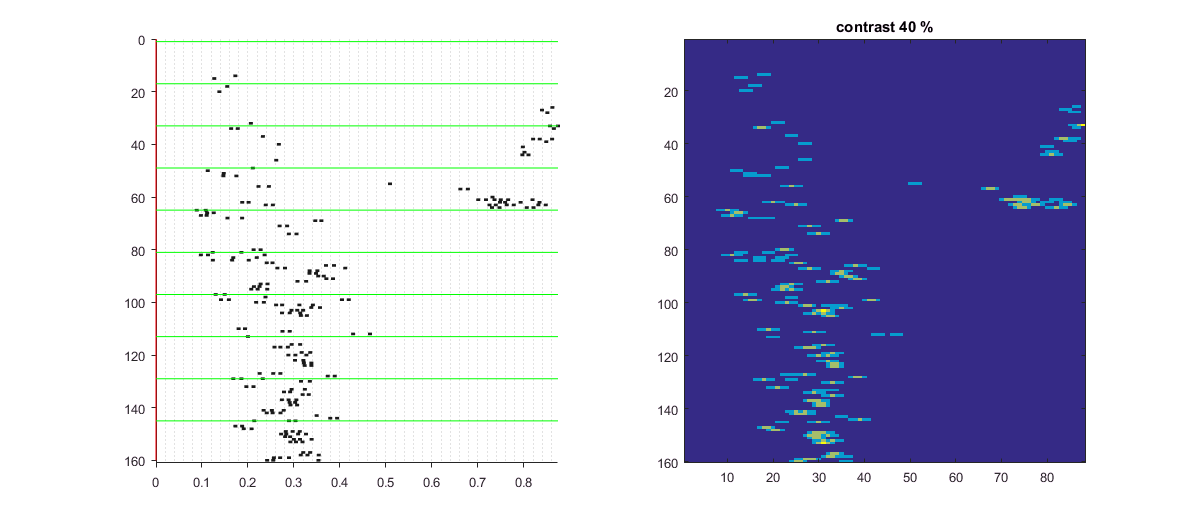

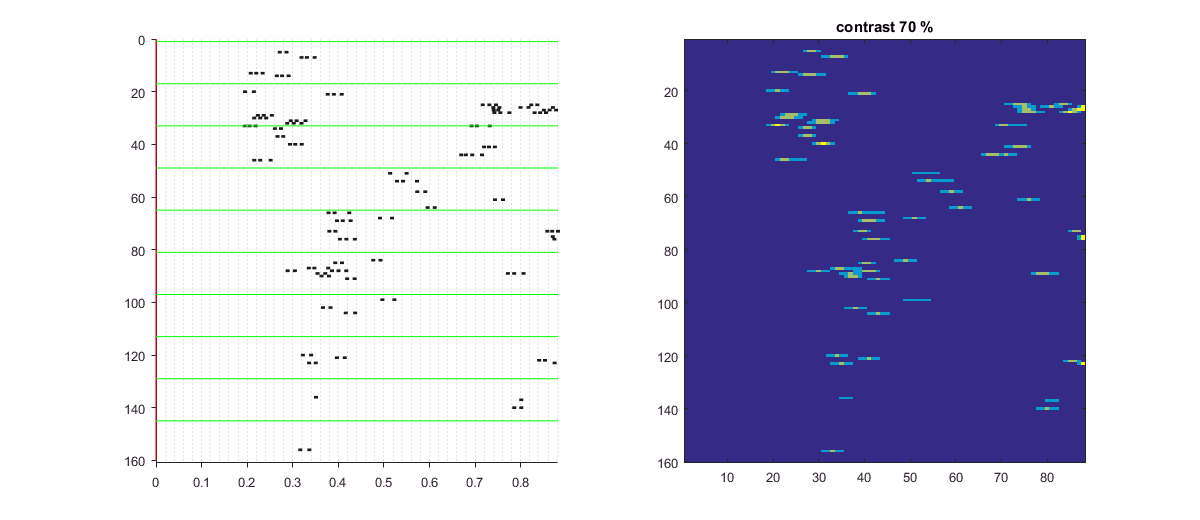

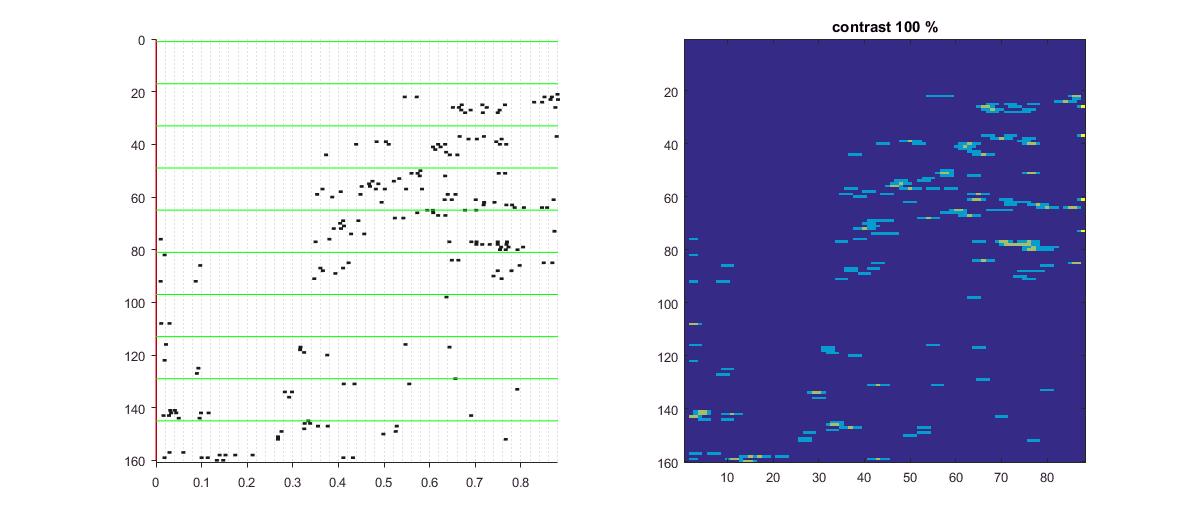

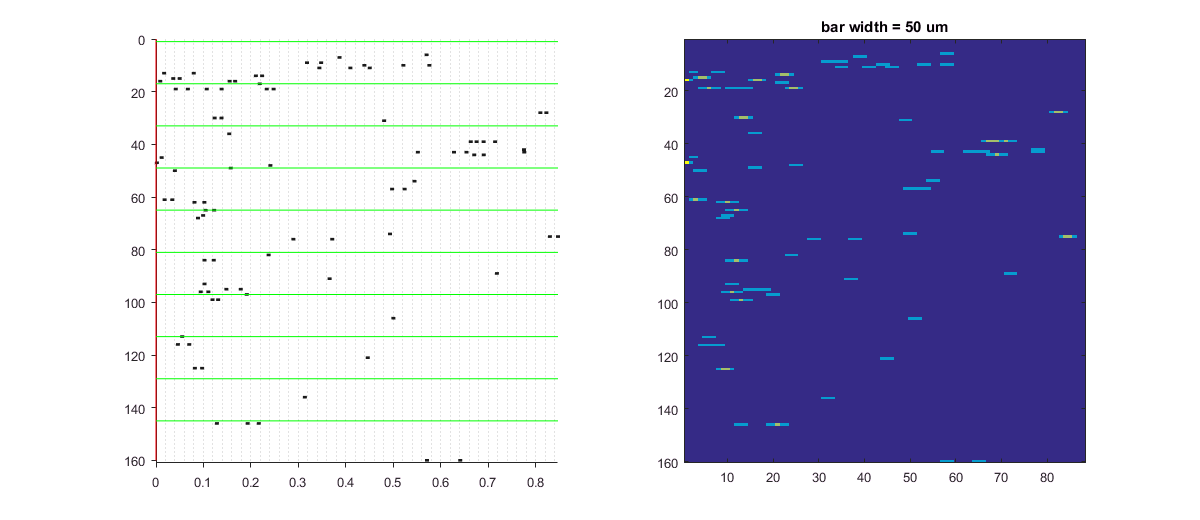

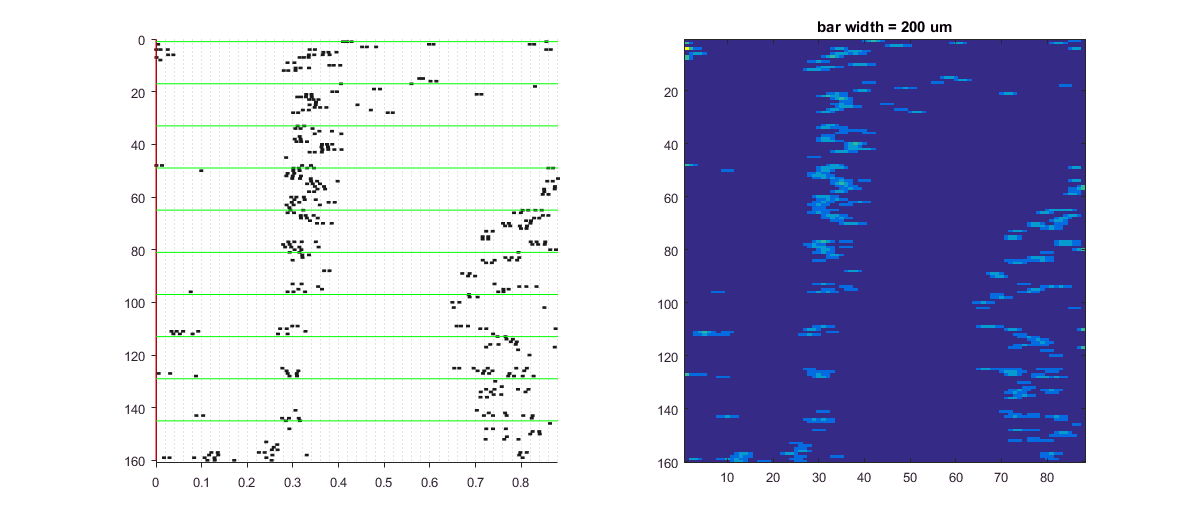

k = 4; % last session

for c = 1:numel(c_range)
    figure; set(gcf, 'Position', [20, 400, 1000, 300]);
    % timestamps is an array of cells over trials whereas rate is an array.
    % Note that ts 
    subplot(1, 2, 1); myraster(spikes_splited{s_id(k)}(c_range{c}), H_lines);
    subplot(1, 2, 2);  imagesc(rate{k}(c_range{c},:));
    title(c_title{c});
end

## 'Firing Rate' @ time window @ spesific condition (i.g. contrast):

Avg & STD over identical repeats

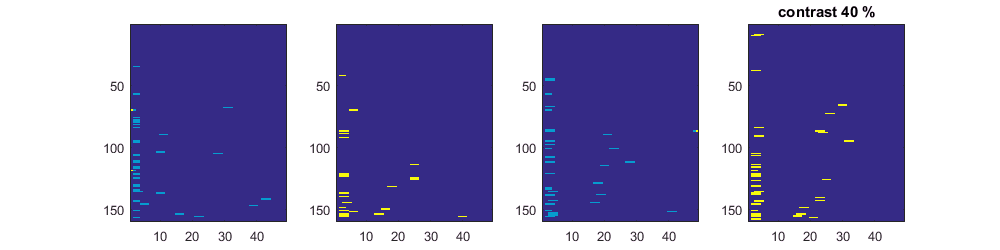

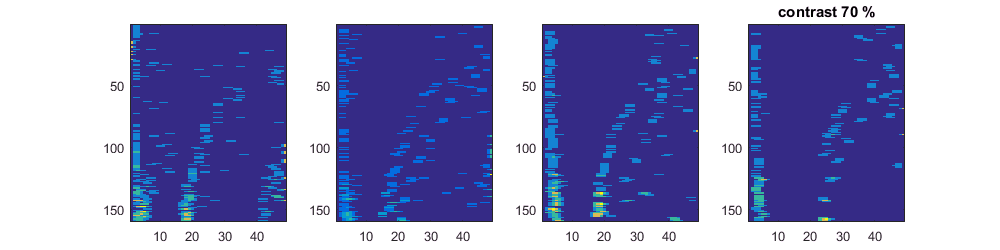

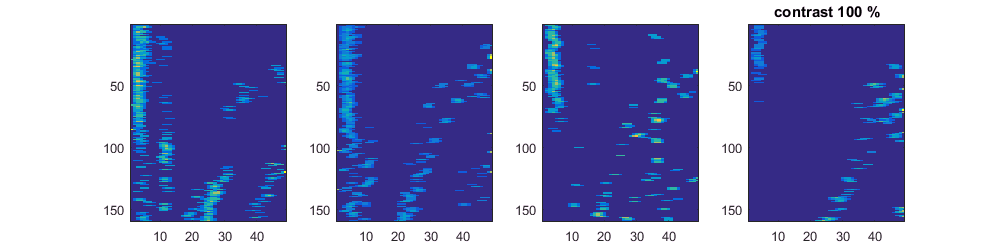

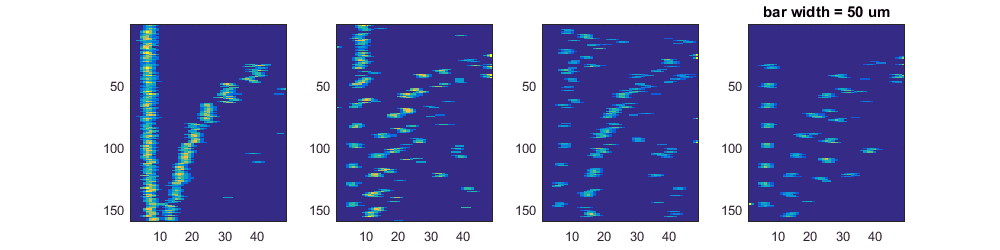

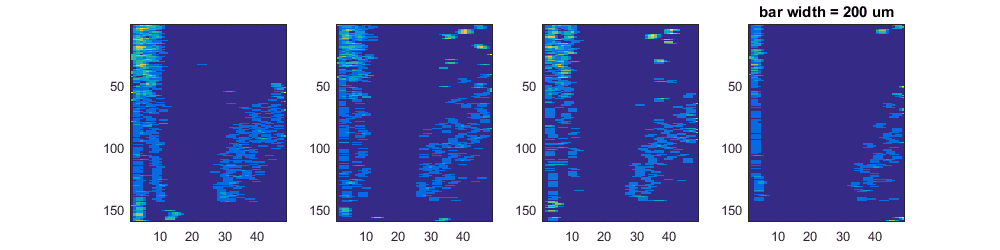

% time window
t_window = [0.05 s_duration];
t_window = [0.060 0.55];
%
bin_size = 0.01;
smoothing = 3;
%
for c = 1:numel(c_range)
    figure; set(gcf, 'Position', [20, 400, 1000, 250]); 
    for i = 1:n_transitions
        subplot(1, n_transitions, i);
        rate{i} = ts_rate_cell(spikes_splited{s_id(i)}(c_range{c}), t_window, bin_size, smoothing); % rate is an array
        % check the image
        imagesc(rate{i});
    end
    title(c_title{c});
end

## Average over repeats, over jitters. Tuning Curves

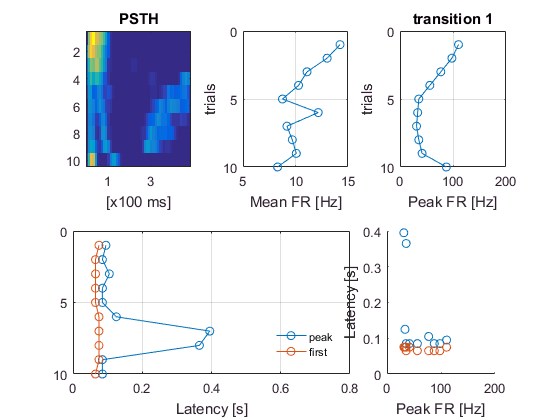

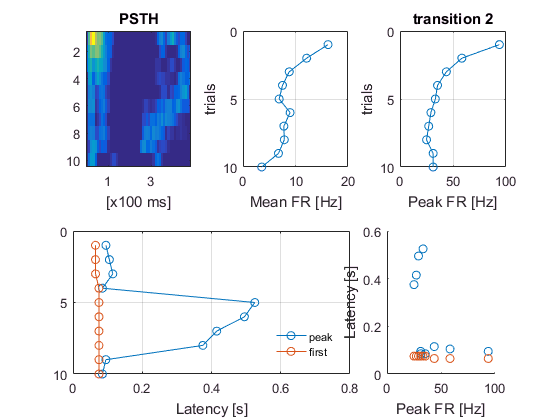

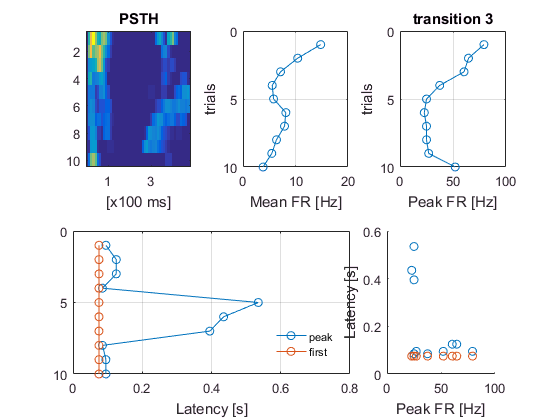

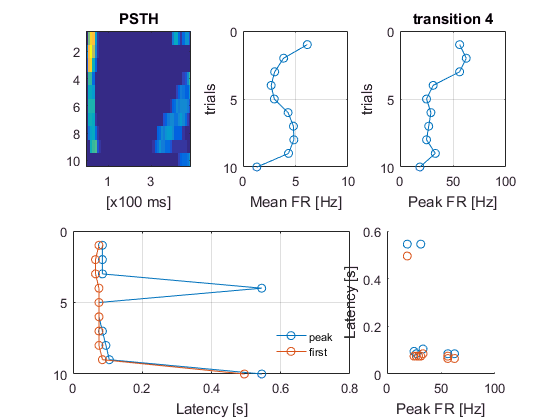

[rate_avg, rate_std] = stat_every_all(    rate, n_repeat);
[rate_avg, rate_std] = stat_every_all(rate_avg, n_jitter);
%
draw_plot = 1;
[mean_r, peak_r, peak_t, first_t] = rate_analysis_all(rate_avg, bin_size, t_window, 'transition', draw_plot);

## Tuning curves with different exp conditions (e.g. speed)

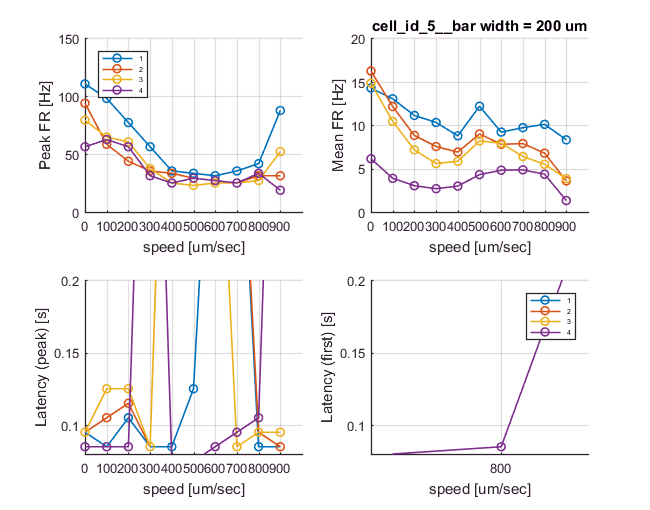

figure; set(gcf, 'Position', [350, 150, 650, 510]);
tuning_param = 0:100:900;
tuning_var = 'speed [um/sec]';
cc_name = ['cell_id_', num2str(j_cell), '__', c_title{c}];
%
subplot(2, 2, 1); [ax, h] = plot_cells(peak_r, tuning_param, {tuning_var, 'Peak FR [Hz]'}, ' '); h.Location = 'northwest';
subplot(2, 2, 2); ax = plot_cells(mean_r, tuning_param, {tuning_var, 'Mean FR [Hz]'}); title(cc_name);
subplot(2, 2, 3); ax = plot_cells(peak_t, tuning_param, {tuning_var, 'Latency (peak) [s]'}, ''); ylim([0.08 0.20]);
subplot(2, 2, 4); ax = plot_cells(first_t, tuning_param, {tuning_var, 'Latency (first) [s]'}, ' '); ylim([0.08 0.20]);
cd(savedir);
saveas(gcf, cc_name, 'png');

%print(gcf, cc_name,'-dpng');


## Data collection from all cells (new graph)

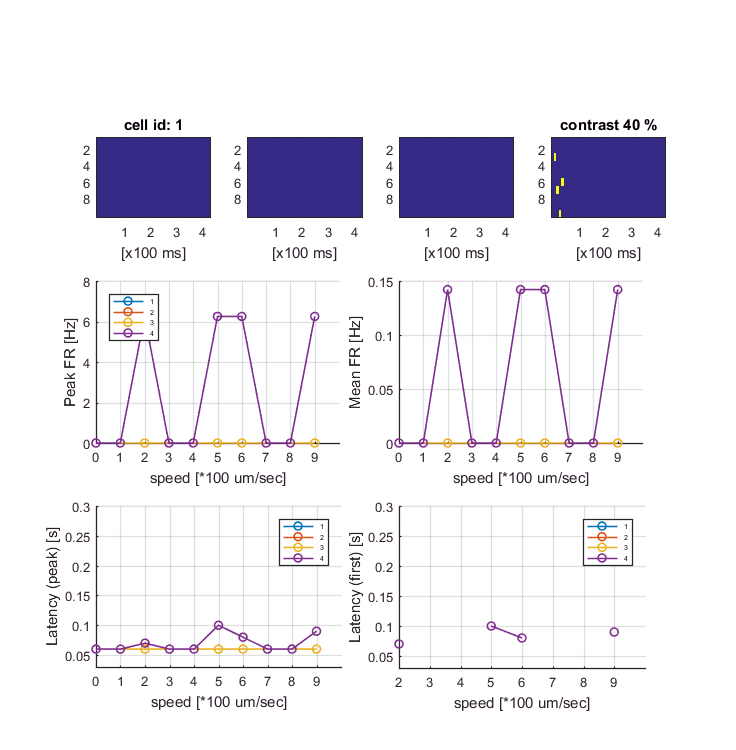

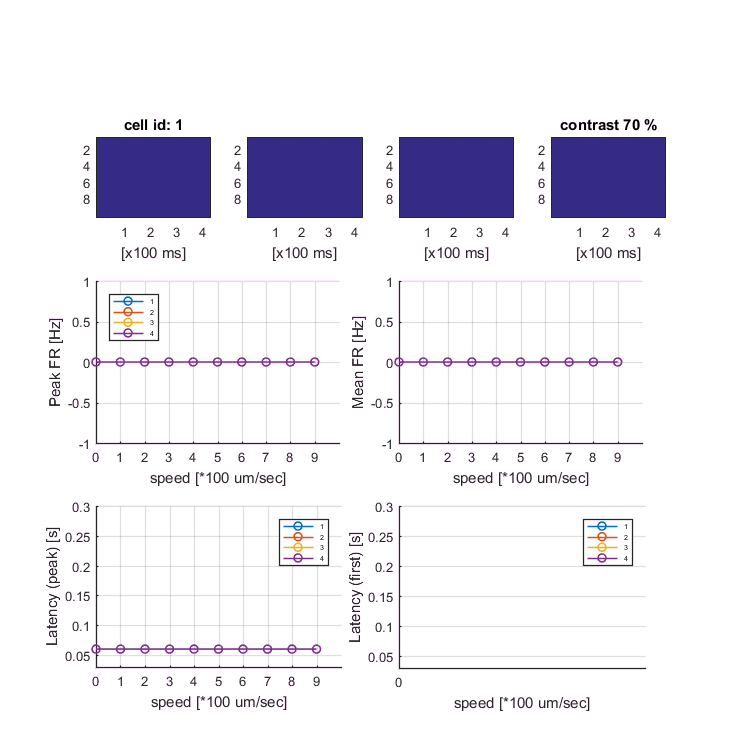

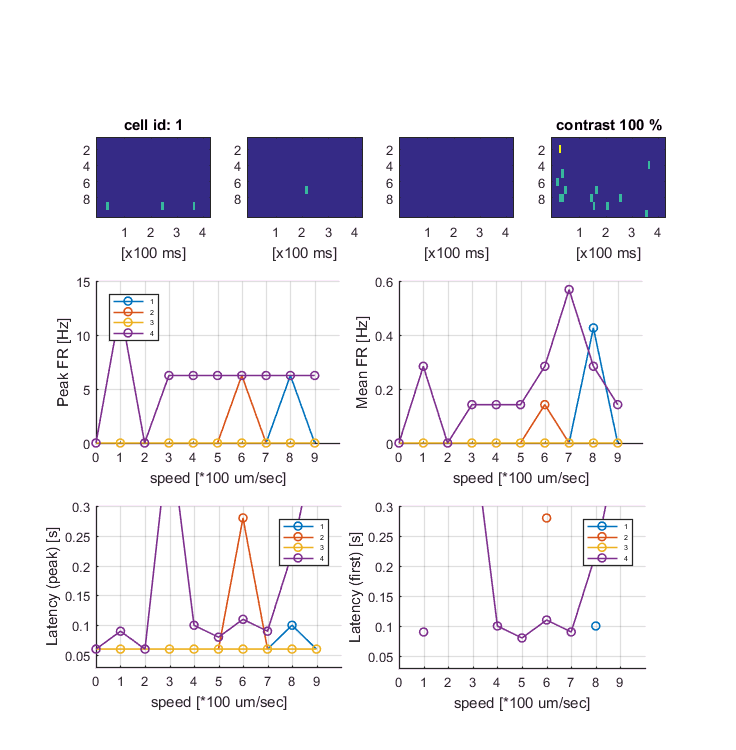

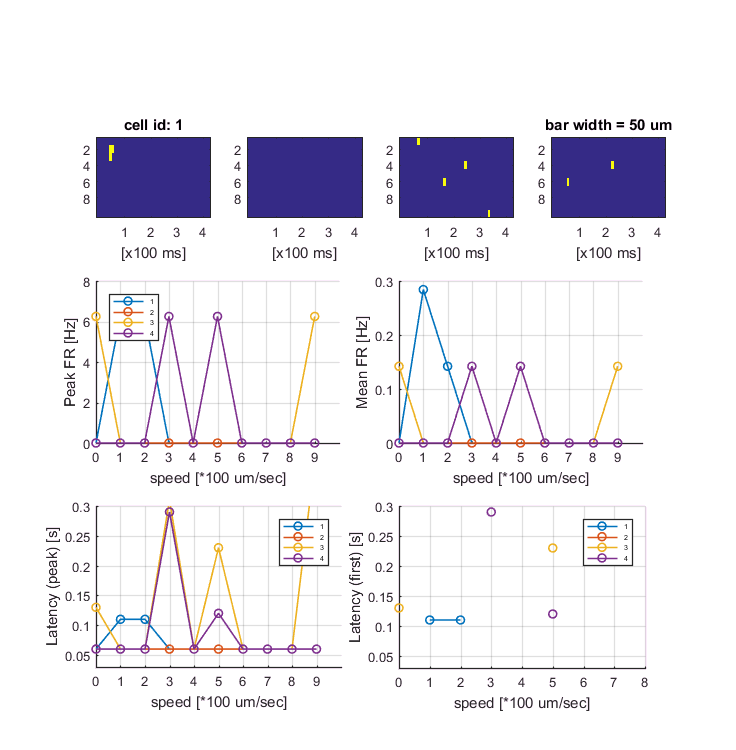

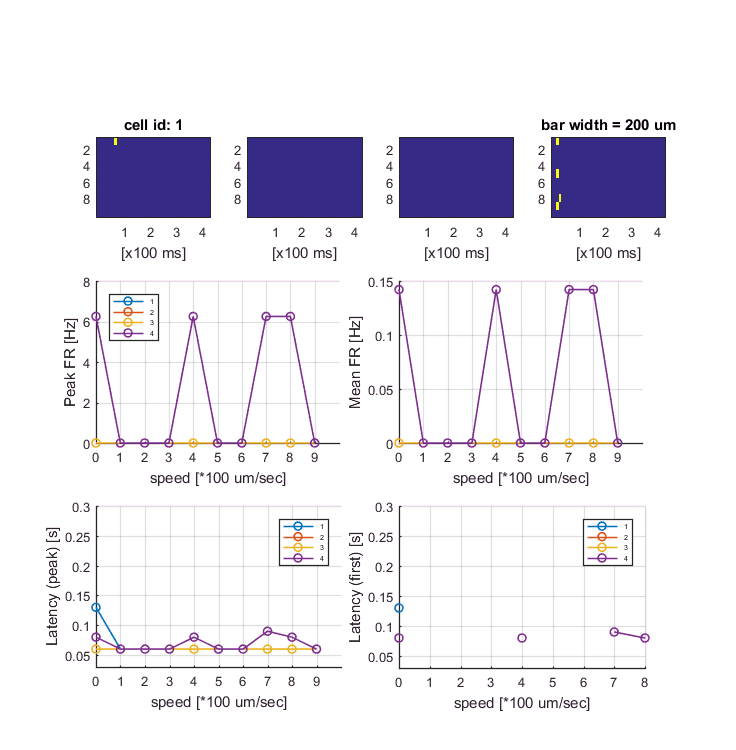

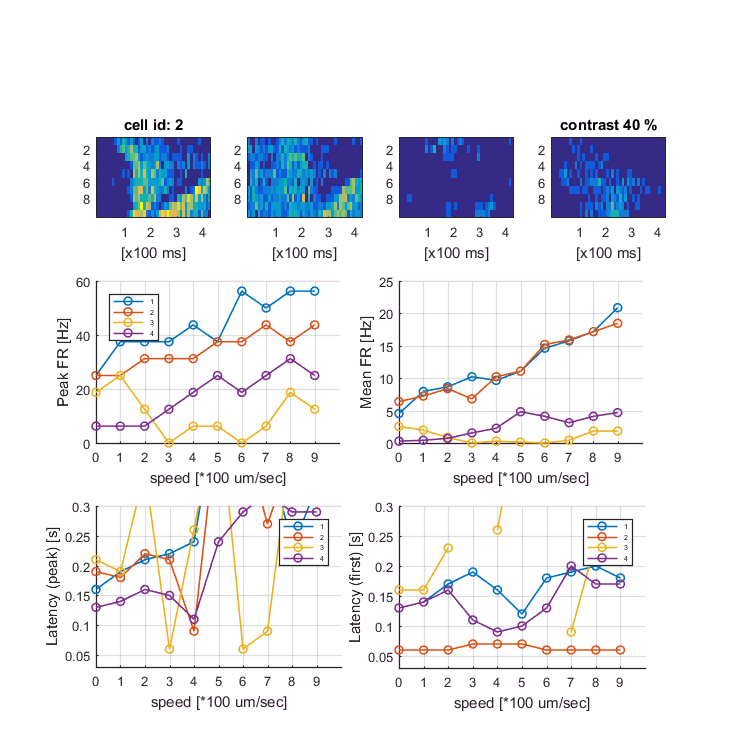

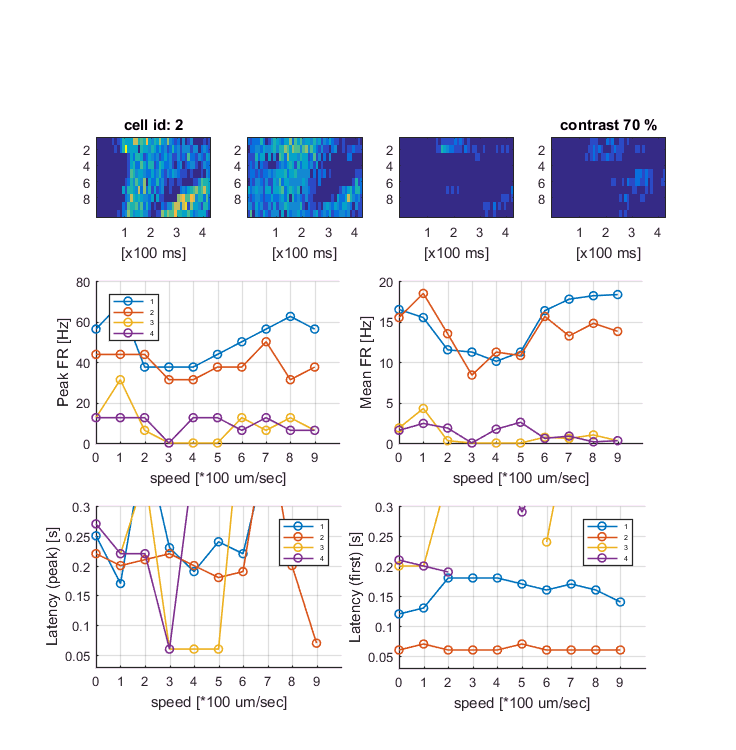

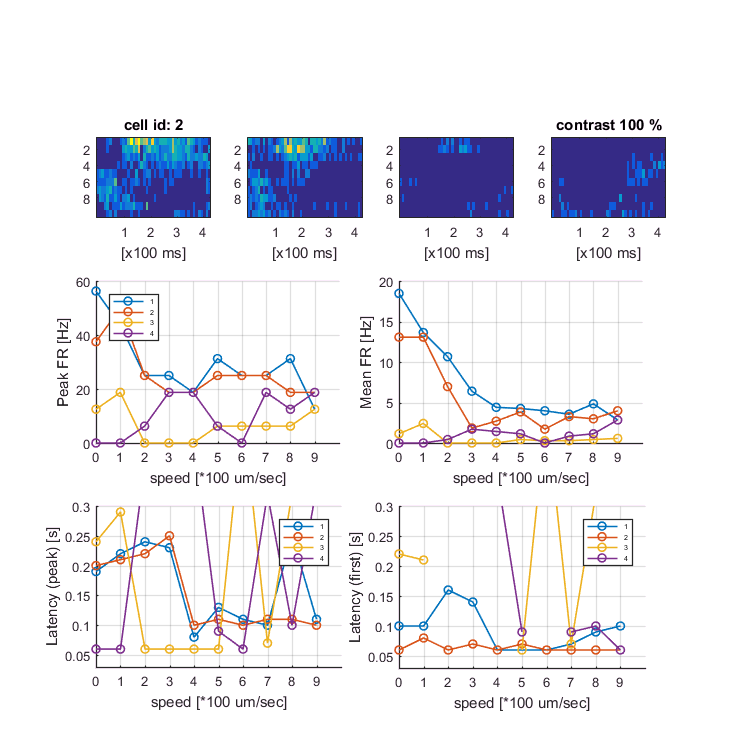

% all_spikes_c : all spikes from an exp data file. It is corrected data after checking abnormal lines.
%
draw_plot = 0;
tuning_param = 0:100:900;
tuning_var = 'speed [*100 um/sec]';
%
t_window = [0.055 0.5];
bin_size = 0.01;
smoothing = 2;
%
t_last = n_bin * bin_size * 1000/100 + t_window(1)*10; % * 100 ms
xtick_label = 1:1:t_last;
ytick_label = 0:2:9;    % ytick of psth
%
rows_plot =3;
%
for j_cell = 1:numel(s) % sorted cells
    
    spikes_splited = split_to_event(all_spikes{j_cell}, ev_session);
    %
    for c = 1:numel(c_range)
        %
        cc_name = ['cell_id_', num2str(j_cell), '__', c_title{c}];
        %
        for i = 1:n_transitions
            rate{i} = ts_rate_cell(spikes_splited{s_id(i)}(c_range{c}), t_window, bin_size, smoothing); % rate is an array
        end
        % average over repeats over jitters
        [rate_avg, rate_std] = stat_every_all(    rate, n_repeat);
        [rate_avg, rate_std] = stat_every_all(rate_avg, n_jitter);
        [mean_r, peak_r, peak_t, first_t] = rate_analysis_all(rate_avg, bin_size, t_window, 'transition', draw_plot);
        %
        [n_exp, n_bin] = size(rate_avg{1});
        r_max = cellfun(@max, rate_avg, 'UniformOutput', 0);
        r_max = cellfun(@max, r_max);
        r_max = max(r_max); if r_max ==0, r_max =1; end;

        xtick_pos = round((xtick_label/10/bin_size)+0.5)+ t_window(1)*10;
        % Rate map
        figure; set(gcf, 'Position', [430, 170, 736, 750]); 
        
        for i = 1:n_transitions
            h = subplot(rows_plot, n_transitions, i); 
            h.Position(3) = 1.0*h.Position(3);
            h.Position(4) = 0.5*h.Position(4); 
            imagesc(rate_avg{i}, [0 r_max]); xlabel('[x100 ms]');
            set(gca, 'XTick', xtick_pos, 'XTickLabel', xtick_label, 'YTick', ytick_label);
            if i == 1
                title(['cell id: ', num2str(j_cell)]);
            end
        end
        title(c_title{c});
        %title(cc_name);
        % Tuning curves
        h_sub = subplot(rows_plot, n_transitions, [1 2]+n_transitions); [ax, h] = plot_cells(peak_r, tuning_param, {tuning_var, 'Peak FR [Hz]'}, ' '); h.Location = 'northwest'; h_sub.Position(3) = 0.91*h_sub.Position(3); 
            ax.XTickLabel = tuning_param/100;
        h_sub = subplot(rows_plot, n_transitions, [3 4]+n_transitions); ax = plot_cells(mean_r, tuning_param, {tuning_var, 'Mean FR [Hz]'}); h_sub.Position(3) = 0.91*h_sub.Position(3);
            ax.XTickLabel = tuning_param/100;
        h_sub = subplot(rows_plot, n_transitions, [1 2]+2*n_transitions); ax = plot_cells(peak_t, tuning_param, {tuning_var, 'Latency (peak) [s]'}, ' '); ylim([-inf inf]); h_sub.Position(3) = 0.92*h_sub.Position(3);
            ylim([0.03 0.3]);
            ax.XTickLabel = tuning_param/100;
        h_sub = subplot(rows_plot, n_transitions, [3 4]+2*n_transitions); ax = plot_cells(first_t, tuning_param, {tuning_var, 'Latency (first) [s]'}, ' '); ylim([-inf inf]); h_sub.Position(3) = 0.92*h_sub.Position(3);
            ylim([0.03 0.3]);    
            ax.XTickLabel = tuning_param/100;
        cd(savedir);
        saveas(gcf, cc_name, 'png');    
    end
end